recObj = audiorecorder(5000,16,1);
recDuration = 2;
fs0 = 5000;
disp("Begin speaking.")

Begin speaking.


recordblocking(recObj,recDuration);
disp("End of recording.")

End of recording.


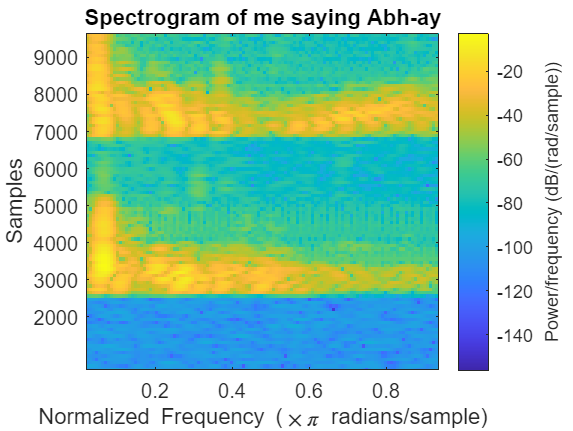

y = getaudiodata(recObj);
window_length = 100; % Length of the Hamming window (samples)
overlap = 10;        % Overlap between consecutive windows (samples)
window_length_2 = 150;

% Create and plot the spectrogram
figure(2);
spectrogram(y, hamming(window_length), overlap);
title('Spectrogram of me saying Abh-ay');